音乐播放完成，已保存为 castle_in_the_sky_strict.wav


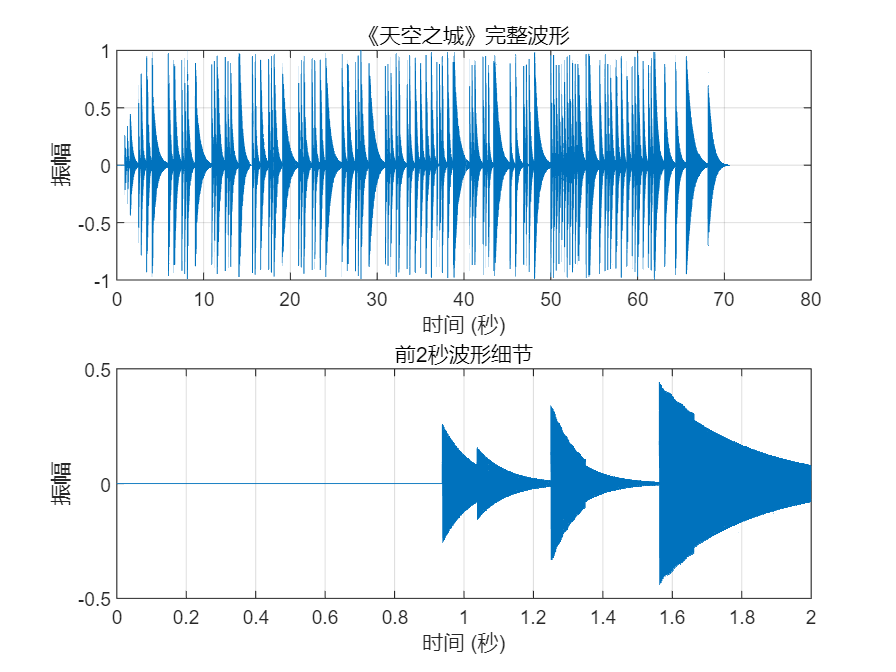

playCastleInTheSky();



%这是练习三的标准代码，后续可能还需要自己修改一下



function playCastleInTheSky()
% 播放《天空之城》主函数 - 严格按照提供的简谱

    fs = 8192; % 采样频率
    baseBeatDuration = 60/96; % 根据谱子标记 1=C4=96，计算每拍时长
    
    % 简谱编码规则：
    % 音符格式: [音符, 八度偏移, 节拍倍数]
    % 音符: 0=休止符, 1-7=音符, 8=i(高音1), 9=ii(高高音1)
    % 八度偏移: 0=中音, 1=高音, -1=低音
    % 节拍倍数: 1=四分音符, 0.5=八分音符, 2=二分音符, 1.5=附点四分音符
    
    % 按照谱子小节编码 (只编码主旋律)
    musicScore = [
        % 第一小节
        0, 0, 0.5; 0, 0, 0.5; 0, 0, 0.5; 6, 0, 0.5; 7, 0, 0.5;
        
        % 第二小节  
        8, 0, 1.5; 7, 0, 0.5; 8, 0, 1; 3, 1, 1;
        
        % 第三小节
        7, 0, 3; 3, 1, 1;
        
        % 第四小节
        6, 1, 1.5; 5, 1, 0.5; 6, 1, 0.5; 8, 1, 1.5;
        
        % 第五小节
        5, 1, 3; 3, 1, 0.5; 3, 1, 0.5;
        
        % 第六小节
        4, 1, 1.5; 3, 1, 0.5; 4, 1, 0.5; 8, 1, 1.5;
        
        % 第七小节
        3, 1, 2; 0, 0, 0.5; 8, 1, 0.5; 8, 1, 1;
        
        % 第八小节
        7, 1, 1.5; 4, 1, 0.5; 4, 1, 0.5; 7, 1, 1.5;
        
        % 第九小节
        7, 1, 3; 6, 1, 0.5; 7, 1, 0.5;
        
        % 第十小节
        8, 1, 1.5; 7, 1, 0.5; 8, 1, 1; 3, 2, 1;
        
        % 第十一小节
        7, 1, 3; 3, 2, 1;
        
        % 第十二小节
        6, 2, 1.5; 5, 2, 0.5; 6, 2, 0.5; 8, 2, 1.5;
        
        % 第十三小节
        5, 2, 3; 3, 2, 0.5; 3, 2, 0.5;
        
        % 第十四小节
        4, 2, 1; 8, 2, 0.5; 7, 2, 1.5; 8, 2, 0.5;
        
        % 第十五小节
        2, 2, 1; 3, 2, 1; 8, 2, 1; 8, 2, 1;
        
        % 第十六小节
        8, 2, 1; 7, 2, 0.5; 6, 2, 0.5; 7, 2, 1; 8, 2, 1;
        
        % 第十七小节
        6, 2, 3; 8, 2, 0.5; 2, 3, 0.5;
        
        % 第十八小节
        3, 3, 1.5; 2, 3, 0.5; 3, 3, 0.5; 5, 3, 1;
        
        % 第十九小节
        2, 3, 3; 5, 3, 1;
        
        % 第二十小节
        8, 3, 1.5; 7, 3, 0.5; 8, 3, 0.5; 3, 4, 1;
        
        % 第二十一小节
        3, 4, 3; 5, 4, 0.5; 5, 4, 0.5;
        
        % 第二十二小节
        6, 4, 0.5; 7, 4, 0.5; 8, 4, 0.5; 2, 4, 0.5; 7, 4, 0.5; 8, 4, 0.5; 2, 4, 0.5; 8, 4, 0.5;
        
        % 第二十三小节
        8, 4, 1.5; 5, 4, 0.5; 5, 4, 2;
        
        % 第二十四小节
        2, 4, 1; 8, 4, 0.5; 7, 4, 0.5; 6, 4, 1;
        
        % 第二十五小节
        8, 4, 1; 2, 4, 1; 8, 4, 1;
        
        % 第二十六小节
        6, 4, 0.5; 7, 4, 0.5; 5, 4, 1; 3, 4, 1; 7, 4, 0.5; 3, 4, 0.5; 5, 4, 2;
        
        % 第二十七小节
        4, 4, 2; 4, 4, 2;
        
        % 第二十八小节
        3, 4, 4; 2, 4, 4;
    ];
    
    % 生成完整音乐波形
    fullWave = [];
    
    for i = 1:size(musicScore, 1)
        note = musicScore(i, :);
        tone = note(1);
        noctave = note(2);
        rhythmMultiplier = note(3);
        
        rhythm = rhythmMultiplier * baseBeatDuration;
        
        % 生成单个音符波形
        if tone == 0 % 休止符
            noteWave = zeros(1, round(fs * rhythm));
        else
            % 将编码转换为实际音符和八度
            if tone == 8 % i (高音1)
                actualTone = 1;
                actualNoctave = noctave + 1;
            elseif tone == 9 % ii (高高音1)
                actualTone = 1;
                actualNoctave = noctave + 2;
            else
                actualTone = tone;
                actualNoctave = noctave;
            end
            
            % 生成音符波形
            noteWave = gen_wave(actualTone, 'C', actualNoctave, 0, rhythm, fs);
        end
        
        % 添加到完整波形
        fullWave = [fullWave, noteWave];
    end
    
    % 应用整体包络衰减函数
    fullWave = apply_global_envelope(fullWave, fs);
    
    % 播放音乐
    sound(fullWave, fs);
    
    % 保存为WAV文件
    audiowrite('castle_in_the_sky_strict.wav', fullWave, fs);
    
    fprintf('音乐播放完成，已保存为 castle_in_the_sky_strict.wav\n');
    
    % 绘制波形图
    plot_waveform(fullWave, fs);
end

function wave = gen_wave(tone, scale, noctave, rising, rhythm, fs)
% 生成单个音符的波形
% 严格按照项目要求实现

    % 如果是休止符，返回静音
    if tone == 0
        wave = zeros(1, round(fs * rhythm));
        return;
    end
    
    % 计算音符频率
    freq = calculate_frequency(tone, scale, noctave, rising);
    
    % 生成时间向量
    t = 0:1/fs:rhythm;
    t = t(1:end-1); % 确保长度正确
    
    % 生成正弦波
    wave = sin(2 * pi * freq * t);
    
    % 应用包络衰减 (指数衰减)
    envelope = exp(-4 * t / rhythm);
    wave = wave .* envelope;
end

function freq = calculate_frequency(tone, scale, noctave, rising)
% 计算音符频率 - 基于十二平均律
    
    % C调基准频率 (中音区)
    cBaseFreq = [261.63, 293.66, 329.63, 349.23, 392.00, 440.00, 493.88];
    
    % 调号偏移 (半音数)
    scaleOffsets = containers.Map(...
        {'C', 'D', 'E', 'F', 'G', 'A', 'B'}, ...
        [0, 2, 4, 5, 7, 9, 11]);
    
    % 十二平均律比例
    semitoneRatio = 2^(1/12);
    
    % 计算基础频率 (C调)
    baseFreq = cBaseFreq(tone);
    
    % 加上调号偏移
    scaleOffset = scaleOffsets(scale);
    baseFreq = baseFreq * (semitoneRatio ^ scaleOffset);
    
    % 加上升降调偏移
    baseFreq = baseFreq * (semitoneRatio ^ rising);
    
    % 加上八度偏移
    freq = baseFreq * (2 ^ noctave);
end

function processedWave = apply_global_envelope(wave, fs)
% 应用整体包络衰减函数到完整波形
% 模拟真实乐器的动态变化

    % 创建时间向量
    t = (0:length(wave)-1) / fs;
    totalDuration = length(wave) / fs;
    
    % 1. 渐入包络 (前5%的时间)
    fadeInDuration = totalDuration * 0.05;
    fadeInSamples = round(fadeInDuration * fs);
    fadeInEnvelope = linspace(0, 1, fadeInSamples);
    
    % 2. 主要部分包络 (中间90%的时间)
    mainDuration = totalDuration * 0.90;
    mainSamples = round(mainDuration * fs);
    
    % 创建轻微动态变化 - 模拟呼吸效果
    mainTime = (0:mainSamples-1) / fs;
    breathEffect = 0.95 + 0.05 * sin(2 * pi * 0.5 * mainTime); % 0.5Hz的轻微波动
    
    % 3. 渐出包络 (最后5%的时间)
    fadeOutDuration = totalDuration * 0.05;
    fadeOutSamples = round(fadeOutDuration * fs);
    fadeOutEnvelope = linspace(1, 0, fadeOutSamples);
    
    % 组合完整包络
    envelope = [fadeInEnvelope, breathEffect, fadeOutEnvelope];
    
    % 确保包络长度与波形匹配
    if length(envelope) > length(wave)
        envelope = envelope(1:length(wave));
    elseif length(envelope) < length(wave)
        envelope = [envelope, zeros(1, length(wave)-length(envelope))];
    end
    
    % 应用包络
    processedWave = wave .* envelope;
    
    % 添加轻微混响效果 (简单的回声)
    processedWave = add_reverb(processedWave, fs, 0.1, 0.3);
end

function output = add_reverb(input, fs, delayTime, decayFactor)
% 添加简单的混响效果
% delayTime: 延迟时间(秒)
% decayFactor: 衰减因子

    delaySamples = round(delayTime * fs);
    
    % 创建延迟版本
    delayed = [zeros(1, delaySamples), input(1:end-delaySamples)];
    
    % 混合原始信号和延迟信号
    output = input + decayFactor * delayed;
    
    % 归一化防止削波
    output = output / max(abs(output));
end

function plot_waveform(wave, fs)
% 绘制波形图

    t = (0:length(wave)-1) / fs;
    
    figure;
    subplot(2,1,1);
    plot(t, wave);
    xlabel('时间 (秒)');
    ylabel('振幅');
    title('《天空之城》完整波形');
    grid on;
    
    % 绘制前2秒的细节
    subplot(2,1,2);
    detailSamples = min(round(2 * fs), length(wave));
    plot(t(1:detailSamples), wave(1:detailSamples));
    xlabel('时间 (秒)');
    ylabel('振幅');
    title('前2秒波形细节');
    grid on;
end